clear all
close all
clc

**Read prices**

filename = 'geo_index_prices_student.xlsx';

table_prices = readtable(filename);

**Transform prices from table to timetable**

dt = table_prices(:,1).Variables;
values = table_prices(:,2:end).Variables;
nm = table_prices.Properties.VariableNames(2:end);

myPrice_dt = array2timetable(values, 'RowTimes', dt, 'VariableNames', nm);


**Selection of subset of Dates**

start_dt = datetime('01/05/2021', 'InputFormat', 'dd/MM/yyyy');
end_dt = datetime('01/08/2021', 'InputFormat', 'dd/MM/yyyy');
rng = timerange(start_dt, end_dt, 'Closed');
subsample = myPrice_dt(rng, :);
prices_val = subsample.Variables;

**Calculate Returns**

LogRet = tick2ret(prices_val,'Method', 'Continuous');
ExpRet = mean(LogRet);

**Calculate Varinace-Covariance Matrix**

V = cov(LogRet);

**1.a Test on Concentration Error**

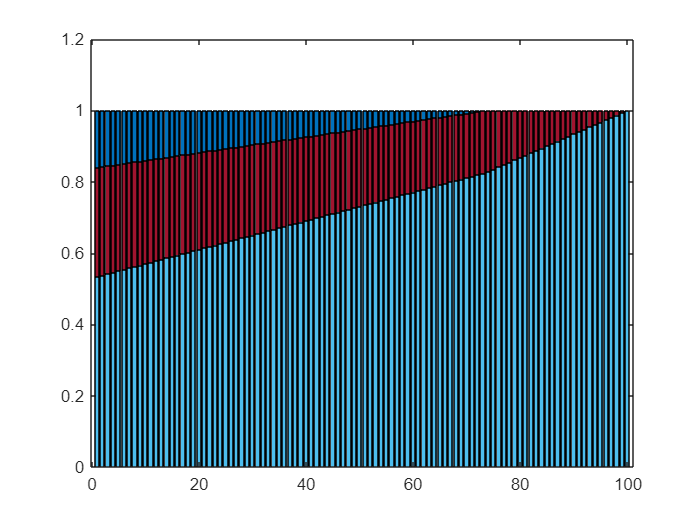

p = Portfolio('AssetList', nm);
p = setDefaultConstraints(p);
P = estimateAssetMoments(p, LogRet, 'missingdata', false);
pwgt = estimateFrontier(P,100);
[pf_Risk, pf_Retn] = estimatePortMoments(P, pwgt);
bar(pwgt', 'stacked')

**1.b Test on Concentration Error**

LowerBound = 0.05*ones(1,8);
UpperBound = 0.8*ones(1,8);
p = setBounds(p, LowerBound, UpperBound);
MinNumAssets = 6;
MaxNumAssets = 8;
p = setMinMaxNumAssets(p, MinNumAssets, MaxNumAssets);
PortBound = estimateAssetMoments(p, LogRet, 'missingdata', false);

pwgt_bound = estimateFrontier(PortBound, 100);
[pf_RiskB, pf_RetnB] = estimatePortMoments(PortBound, pwgt_bound);

h = figure;
bar(pwgt', 'Stacked')

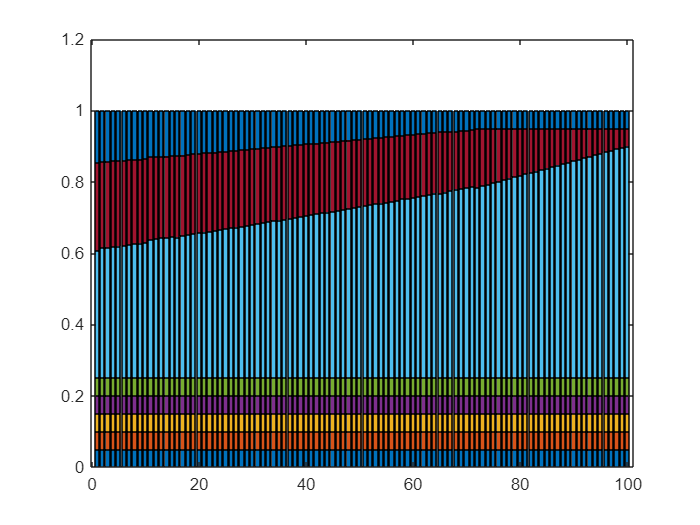

g = figure;
bar(pwgt_bound', 'Stacked')

**2.a Test the robustness of the frontier: We add a small perturbation on the return of one asset**

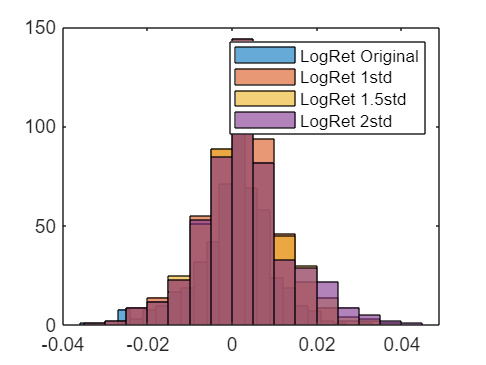

LogRet1 = LogRet;
LogRet1(:,1) = LogRet1(:,1) + std(LogRet1(:,1));

LogRet2 = LogRet;
LogRet2(:,1) = LogRet2(:,1) + 1.5 * std(LogRet2(:,1));

LogRet3 = LogRet;
LogRet3(:,1) = LogRet3(:,1) + 2 * std(LogRet3(:,1));

figure;
histogram(LogRet, 'EdgeAlpha', 0.8)
hold on
histogram(LogRet1, 'EdgeAlpha', 0.8)
histogram(LogRet2,'EdgeAlpha', 0.6)
histogram(LogRet3, 'EdgeAlpha', 0.4)
legend('LogRet Original', 'LogRet 1std', 'LogRet 1.5std', 'LogRet 2std')

**2.b Test the robustness of the frontier: COMPUTE EFFICIENT FRONTIERS**

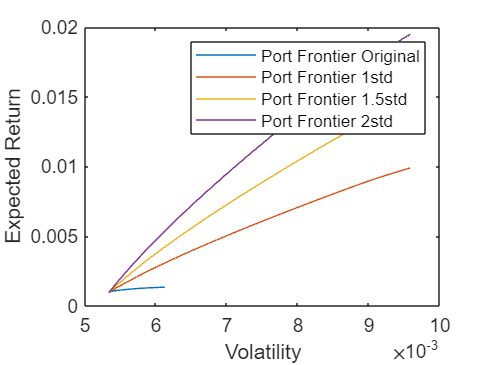

p = Portfolio('AssetList', nm);
p = setDefaultConstraints(p);
Port = estimateAssetMoments(p, LogRet, 'MissingData', false);
pwgt = estimateFrontier(Port, 100);
[pf_risk, pf_Retn] = estimatePortMoments(Port, pwgt);

Port1 = estimateAssetMoments(p, LogRet1, 'MissingData', false);
pwgt1 = estimateFrontier(Port1, 100);
[pf_risk1, pf_Retn1] = estimatePortMoments(Port1, pwgt1);

Port2 = estimateAssetMoments(p, LogRet2, 'MissingData', false);
pwgt2 = estimateFrontier(Port2, 100);
[pf_risk2, pf_Retn2] = estimatePortMoments(Port2, pwgt2);

Port3 = estimateAssetMoments(p, LogRet3, 'MissingData', false);
pwgt3 = estimateFrontier(Port1, 100);
[pf_risk3, pf_Retn3] = estimatePortMoments(Port3, pwgt3);

figure;
title('Portfolio Frontiers')
plot(pf_risk,pf_Retn)
hold on
plot(pf_risk1, pf_Retn1)
plot(pf_risk2, pf_Retn2)
plot(pf_risk3, pf_Retn3)

legend('Port Frontier Original', 'Port Frontier 1std', 'Port Frontier 1.5std', 'Port Frontier 2std')
xlabel('Volatility')
ylabel('Expected Return')

**3. Robust Frontier: Resampling - N simulations of returns assuiming they**

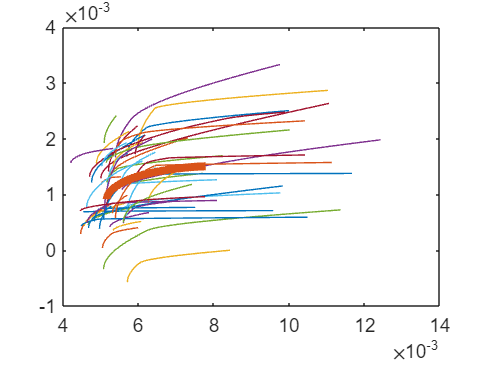

N = 50;
RiskPtfSim = zeros(100, N);
RetPtfSim = zeros(100, N);

for n = 1:N
    R = mvnrnd(ExpRet, V, length(LogRet));
    NewExpRet = mean(R);
    NewCov = cov(R);

    Psim = setAssetMoments(p, NewExpRet, NewCov);
    %Psim = estimateAssetMoments(R);
    w_sim = estimateFrontier(Psim, 100);
    [pf_riskSim, pf_RetSim] = estimatePortMoments(Psim, w_sim);
    RetPtfSim(:,n) = pf_RetSim;
    RiskPtfSim(:,n) = pf_riskSim;
end
figure;
plot(RiskPtfSim, RetPtfSim)
hold on
plot(mean(RiskPtfSim,2),mean(RetPtfSim,2),'LineWidth',4)

**4. Robust Frontier: Robust Estimator**

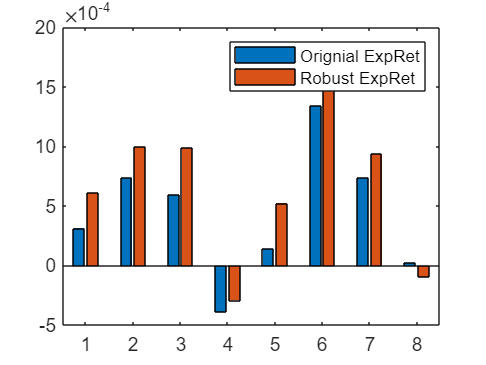

RobustExpRet = trimmean(LogRet,10); %we remove the 10% of the outliers
RobustV = robustcov(LogRet);

x = [1,2,3,4,5,6,7,8];
m = [ExpRet; RobustExpRet];
figure;
bar(x,m );
legend('Orignial ExpRet', 'Robust ExpRet')

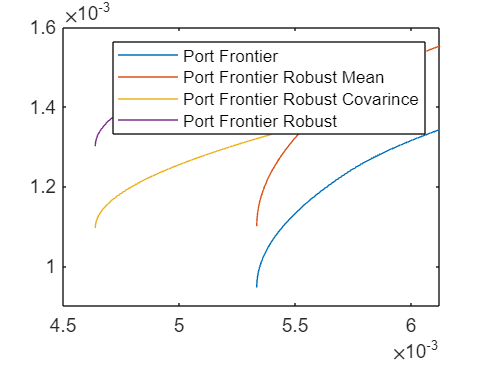

% Create Portfolio and Compute Frontier
p = Portfolio('AssetList', nm);
p = setDefaultConstraints(p);
Port = estimateAssetMoments(p, LogRet);
pwgt = estimateFrontier(Port, 100);
[pf_risk, pf_Retn] = estimatePortMoments(Port, pwgt);
% Robust Mean:
PortRobustMean = setAssetMoments(p, RobustExpRet,V);
pwgtRobustMean = estimateFrontier(PortRobustMean, 100);
[pf_riskRM, pf_RetnRM] = estimatePortMoments(PortRobustMean, pwgtRobustMean);

PortRobustCov = setAssetMoments(p, ExpRet,RobustV);
pwgtRobustCov = estimateFrontier(PortRobustCov, 100);
[pf_riskRC, pf_RetnRC] = estimatePortMoments(PortRobustCov, pwgtRobustCov);

PortRobust = setAssetMoments(p, RobustExpRet,RobustV);
pwgtRobust = estimateFrontier(PortRobust, 100);
[pf_riskRobust, pf_RetnRobust] = estimatePortMoments(PortRobust, pwgtRobust);

figure;
plot(pf_risk, pf_Retn)
hold on
plot(pf_riskRM, pf_RetnRM)
plot(pf_riskRC, pf_RetnRC)
plot(pf_riskRobust, pf_RetnRobust)
legend('Port Frontier', 'Port Frontier Robust Mean', 'Port Frontier Robust Covarince', 'Port Frontier Robust')

**5. Robust Frontier: Shrinkage Estimators -> Bayes-Stain Estimator**

N = R;
T = length(LogRet);
e = ExpRet;
lambda = ((N+2)*(T-1))/(((e-ones(1,8).*mean(e))*inv(V)*(e-ones(1,8).*mean(e)))*(T-N-2));

Error using  * 
Incorrect dimensions for matrix multiplication. Check that the number of columns in the first matrix matches the number of rows in the second matrix. To operate on each element of the matrix individually, use TIMES (.*) for elementwise multiplication.

Related documentation

alpha = lambda./(lambda+T);
BSmean = (1-alpha).*e+alpha.*ones(1,8).*mean(e);

p = Portfolio('AssetList', nm);
p = setDefaultConstraints(p);
PortBS = setAssetMoments(p, BSmean, V);
pwgtBS = estimateFrontier(PortBS, 100);
[pf_riskBS, pf_RetBS] = estimateFrontier(PortBS, pwgtBS);

figure;
plot(pf_risk, pf_Retn,'LineWidth', 2)
hold on
plot(pf_riskBS, pf_RetnBS,'LineWidth', 2)
plot(pf_riskRobust, pf_RetnRobust,'LineWidth', 2)
plot(mean(pf_riskSim,2), mean(pf_RetnSim,2),'LineWidth', 2)
legend('Original Frontier','Bayes-Stein Frontier','Robust Estimator Frontier', 'Resampled Frontier')